# Grating couplers – experimental data

Use the Matlab code below to download and plot the measurement data. The data is for two TE grating couplers, connected with a short waveguide (about 150 microns).

Instead of using the code to download a specific file you can also upload the data file yourself.

**Note: **Ensure you are viewing in either "Output right" or "Output inline" to see the code.

% Enter the Dropbox URL here.  Make sure it has a =1 at the end:
url = 'https://www.dropbox.com/s/1rvjfef4jqybc12/ZiheGao_MZI2_271_Scan1.mat?dl=1';
% or same file from aws:
url = 'https://s3.amazonaws.com/edx-course-phot1x-chrostowski/Phot1x/ZiheGao_MZI2_271_Scan1.mat'

url = 'https://s3.amazonaws.com/edx-course-phot1x-chrostowski/Phot1x/ZiheGao_MZI2_271_Scan1.mat'

Choose which Fibre array port to view

PORT=1; % Which Fibre array port is the output connected to?

a=websave('a.mat',url); % get data from Dropbox
load('a.mat');

% Data is stored in variable "scanResults".
% There are two columns - wavelength (1), and amplitude (2)
lambda=scanResults(1,PORT).Data(:,1)/1e9;
amplitude=scanResults(1,PORT).Data(:,2);

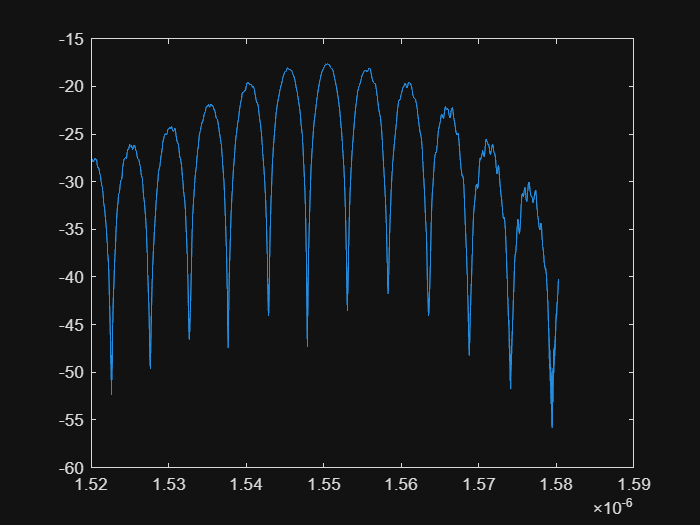

plot(lambda,amplitude)